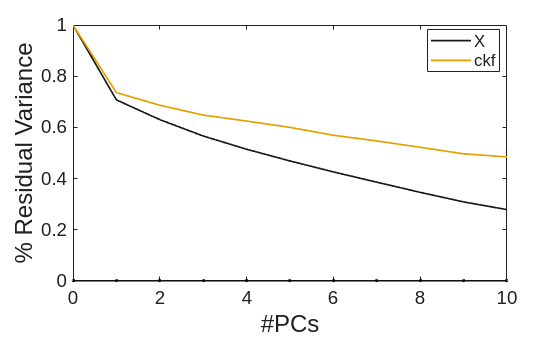

varPca(X_unfold, "PCs", 1:10, "Preprocessing", 0, "PlotCkf", true);

model.lvs=1:2;
model = pcaEig(X_unfold,'PCs',model.lvs);
model.var = trace(X_unfold'*X_unfold);

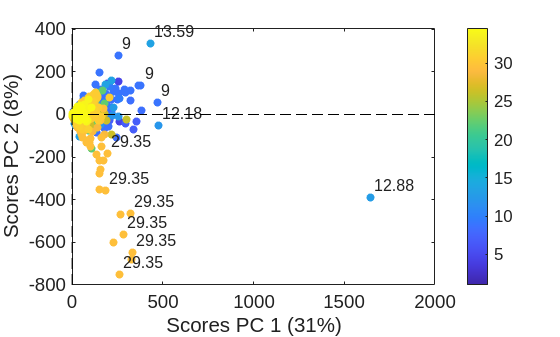

F_subject = string(F_subject);
classification = F_n_subtractions;
scores(model, "ObsLabel", classification, "ObsClass", classification, "Color", "parula");

legend("off");

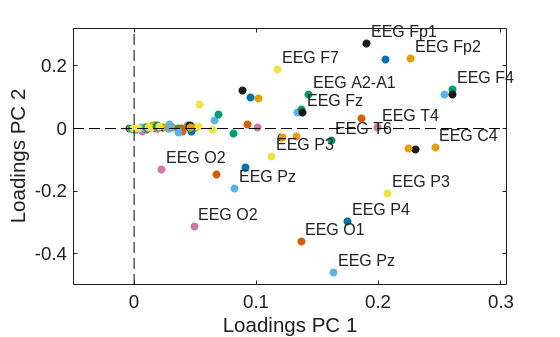

channels = string(channels);
classification = channels;

loadings(model, "VarsLabel", channels, "VarsClass", channels, "Color", "okabeIto");
legend("off")

# ASCA

F_subject = string(F_subject)';
F_genders = string(F_genders)';

% F = [F_subject; F_ages; F_genders; F_rec_years; F_quality; F_operations; F_n_subtractions];
F = [F_genders; F_operations];

[T, parglmo] = parglm(X_unfold, F, 'Preprocessing',0, 'Model', 'linear');

Out of memory.

Error in pinv (line 22)
[U, s, V] = svd(A, 'econ', 'vector');
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in parglm (line 395)
pD =  pinv(D'*D)*D';
^^^^^^^^^^^^^^^^^^^^
Related documentation

ascao = asca(parglmo);

T